#      Antenna Array Processing

##                                            HW7

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/09/10      

clear; clc; close all;

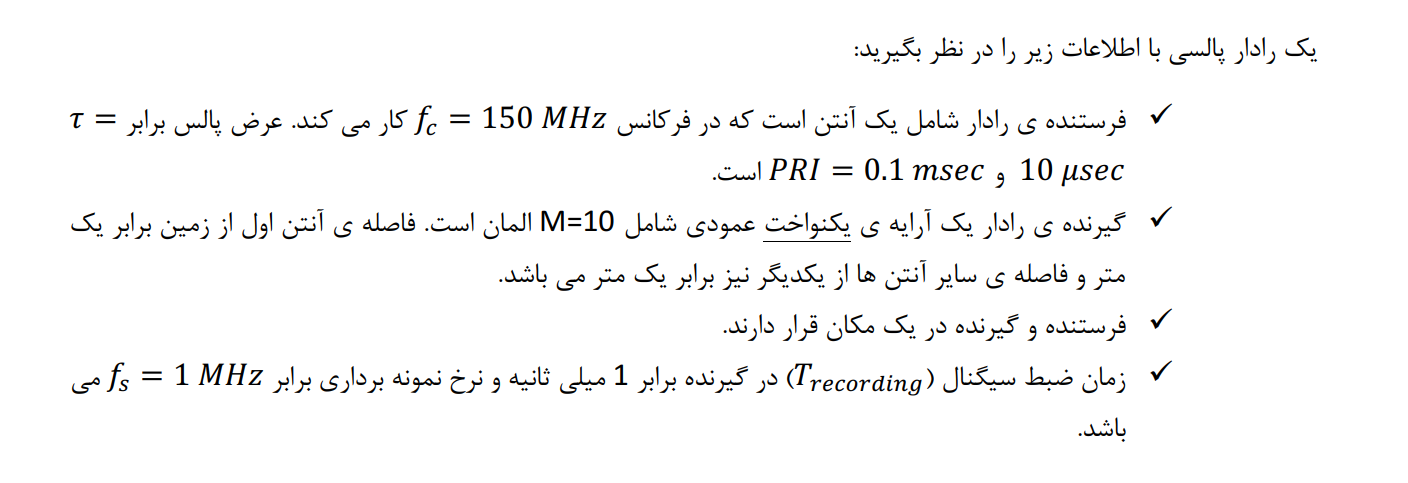



fs = 1e6; % 1MHz
ts = 1/fs;

Trecord = 1e-3; % 1ms
delta_f = 1/Trecord;


t = 0 : ts : Trecord-ts;
freq = -fs/2 : delta_f : fs/2-delta_f;

fc = 150e6; % 150MHz

c = 3e8;
Lambda = c/fc;
k = 2*pi*fc/c ; % 2pi/lambda = 2pif/c

Tau  = 10e-6; % 10us
Tau_num = round(Tau/ts);

PRI  = 0.1e-3; % 0.1ms
PRF = 1/PRI;
PRI_num = round(PRI/ts);
pulse_num = round(Trecord/PRI); % Kolle Pulse ma chanta PRI hast!
sample_num = round(Trecord/ts); % Kolle Pulse ma chanta nemoone hast

% Uniform Array
M = 10;
h = 1; % height of first element from Ground
d = 1; % distance of each element from the next
D = h + d*(0:M-1);


## Plot of Low-Pass Signal:

The same as previous HWs:

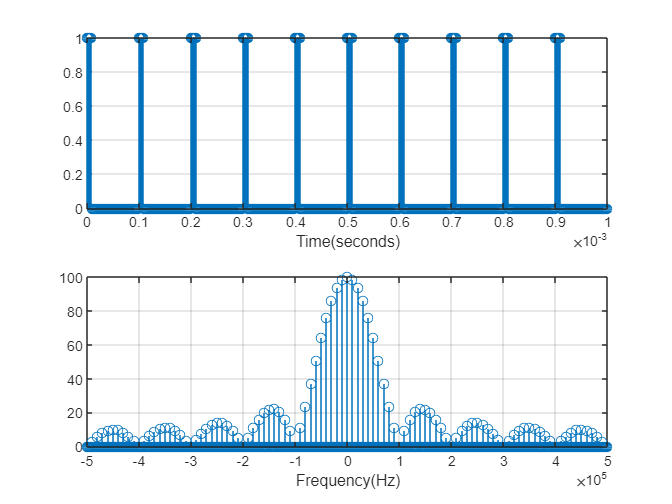

SL_PRI=[ones(1,Tau_num) zeros(1,PRI_num-Tau_num)];
sl=repmat(SL_PRI,1,pulse_num); % Repeat The Baseband SIgnal for each PRI in total Pulse Length

figure(1)
subplot(2,1,1)
stem(t,sl)
xlabel('Time(seconds)')
grid on
subplot(2,1,2)
slf=fftshift(fft(sl));
stem(freq,abs(slf));
xlabel('Frequency(Hz)');
grid on

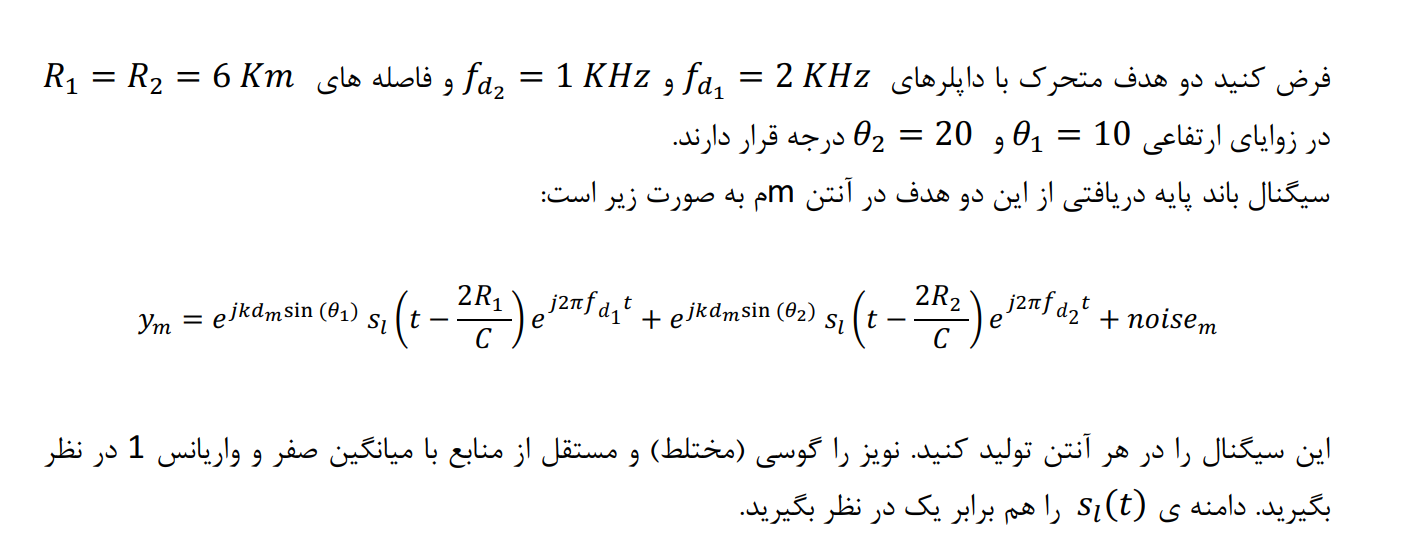

% Target 1:
theta_1= 10*pi/180;
fd1 = 2e3; % 2KHz
R1 = 6e3; % 6Km


% Target 2:
theta_2  = 20*pi/180;
fd2 = 1e3; % 1KHz
R2 = 6e3; % 6Km



% Noise Generation:  Independent from Signals! -- Gaussian --- Zero Mean:
Noise = randn(M, length(t)) + 1j*randn(M, length(t));  % M*T Noise Matrix for M elements of Antenna and T samples
Noise = Noise/sqrt(2);


Y =  exp(1j*k*D'*sin(theta_1) ) .* circshift(sl , floor(2*R1/c) ) .* exp(1j*2*pi*fd1*t)  + ... % Target 1
     exp(1j*k*D'*sin(theta_2) ) .* circshift(sl , floor(2*R2/c) ) .* exp(1j*2*pi*fd2*t);


Y_noisy = Y + Noise;



## Plotting the Received Signal At Terminals:

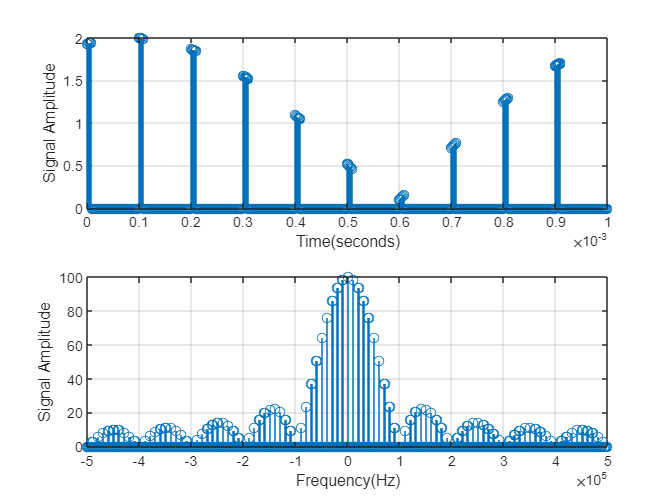


figure(2)
y_in=Y(randi(10,1), :); % Choose a random Terminal to plot its received Signal
y_in_f=fftshift(fft(y_in));


subplot(2,1,1)
stem(t,abs(y_in))
xlabel('Time(seconds)')
ylabel("Signal Amplitude")
grid on

subplot(2,1,2)
stem(freq,abs(y_in_f))
xlabel('Frequency(Hz)')
ylabel("Signal Amplitude")
grid on

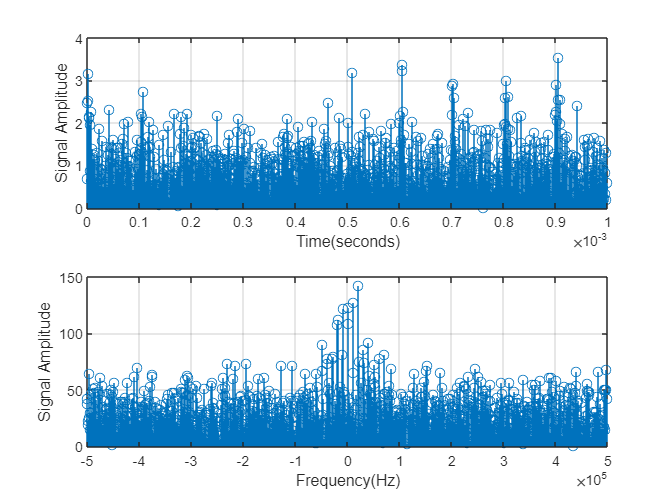


figure(3)
y_in_noisy=Y_noisy(randi(10,1), :); % Choose a random Terminal to plot its received Signal
y_in_noisy_f=fftshift(fft(y_in_noisy));


subplot(2,1,1)
stem(t,abs(y_in_noisy))
xlabel('Time(seconds)')
ylabel("Signal Amplitude")
grid on

subplot(2,1,2)
stem(freq,abs(y_in_noisy_f))
xlabel('Frequency(Hz)')
ylabel("Signal Amplitude")
grid on

## BeamForming:

The Projection of Steering Vectors on Signal Space! --> Maximize this Likelihood and the answer return the corresponding angle where the target is located.

[U, S, V] = svd(Y_noisy); % SVD Decomposition!
disp(S(:,1:20)) % M*T Matrix! --> Diagnal Elements have Values  

  Columns 1 through 9

   47.6796         0         0         0         0         0         0         0         0
         0   42.3816         0         0         0         0         0         0         0
         0         0   33.4834         0         0         0         0         0         0
         0         0         0   32.8863         0         0         0         0         0
         0         0         0         0   31.9854         0         0         0         0
         0         0         0         0         0   31.0141         0         0         0
         0         0         0         0         0         0   30.5152         0         0
         0         0         0         0         0         0         0   30.3211         0
         0         0         0         0         0         0         0         0   29.6662
         0         0         0         0         0         0         0         0         0

  Columns 10 through 18

         0         0         0         0 

It is obvious that only the first 2 values originate from existance of targets and the rest are the result of having Noise in our Terminals! < K=2; also it is obvious that Noise levels are kind of the same in power/Energy represented on diagnal elements of S! > 

K = 2;  % Number of Targets   ----  Known but chosen wisely from SVD result 

Usig = U(:, 1:K);  % M*K
Unull = U(:, K+1:end); % M* (M-K)

Vsig = V(:, 1:K); % T * K
Vnull = V(:, K+1:end); % T * (M-K)


Beamforming --- >>>>  maximize this objective function to find Direction of Arrival!


$$g\left(\theta \right)=|{a\left(\theta \;\right)}^{\prime } *U_{\mathrm{sig}} |_2^2$$


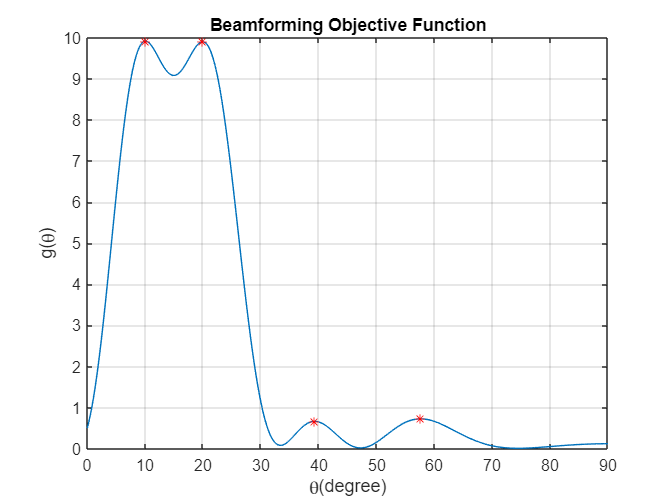

theta = 0 : 0.5e-1 : 90;
a = exp(1j*k*D'*sind(theta)); % Steering Vector
g = sum(abs(a'*Usig).^2, 2); % g(theta)

figure(4)
plot(theta, g)
xlabel('\theta(degree)')
ylabel('g(\theta)')
grid on
title("Beamforming Objective Function")
[Beamforming_peaks , Beamformingidx ] = findpeaks(g);
hold on
plot(theta(Beamformingidx),Beamforming_peaks,"r*")

## MUSIC:

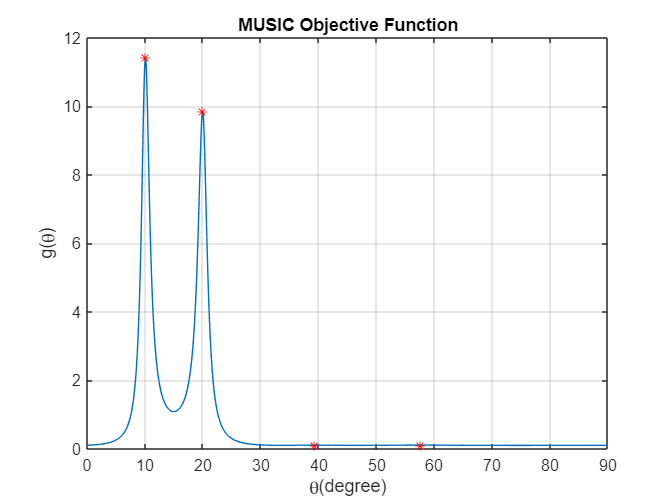

theta = 0 : 0.5e-1 : 90;
a = exp(1j*k*D'*sind(theta)); % Steering Vector
f = 1./sum(  abs(a'*Unull).^2 ,2 ); % f(theta)

figure(5)
close all;
plot(theta, f)
xlabel('\theta(degree)')
ylabel('g(\theta)')
grid on
title("MUSIC Objective Function")
[Music_peaks , Music_idx ] = findpeaks(f);
hold on
plot(theta(Music_idx),Music_peaks,"r*")

It is clear, that the peaks in MUSIC, are sharper than those in Beamforming Method due to Dimension Dominance of the Unull over the Usig!

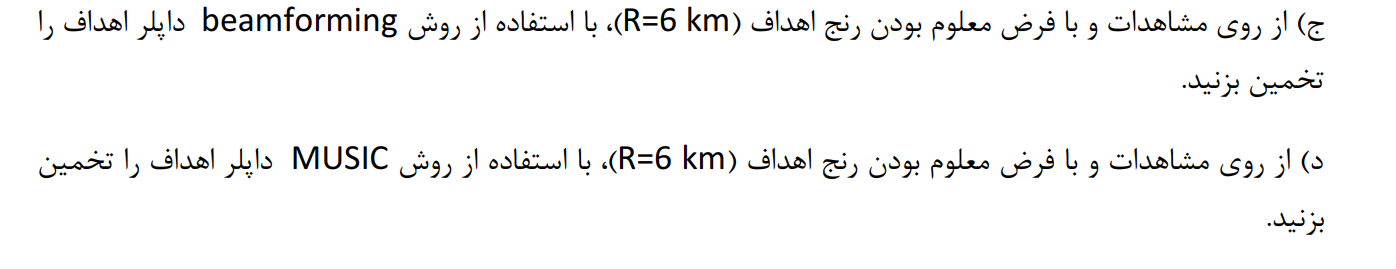

% To find Doppler of a target, we must perform our operation over S
% obtained in SVD decomposition and use projection over Vsig , Vnull to
% decide Range+Doppler for a target!


Maximize Below objective function 


$$g\left(\theta \right)=|{s\left(R,f_d \;\right)}^{\prime } *V_{\mathrm{sig}} |_2^2$$


gives Beamforming  result for the Doppler! of a target

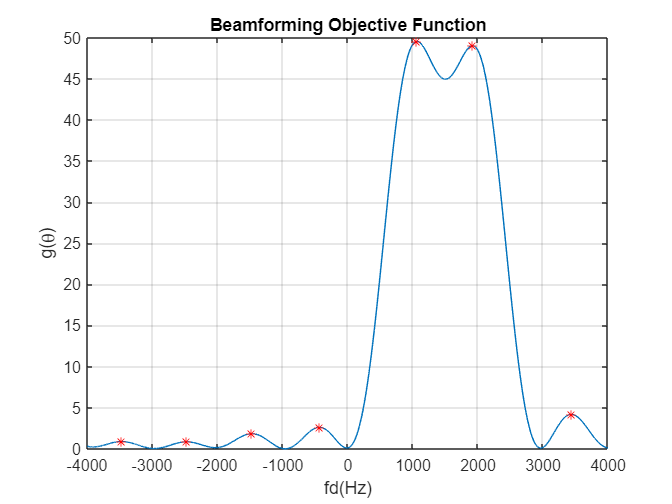

fd = (-4e3 : 1 : 4e3)'; % The Value to be found is the doppler of the targets!
s = circshift(sl , floor(2*R1/c) ).* exp(1j*2*pi*fd*t); % Signal Space with given Range  
g = sum(  abs(s*Vsig).^2 ,2 ); % g(fd)

figure(6)
close all;
plot(fd , g)
xlabel('fd(Hz)')
ylabel('g(\theta)')
grid on
title("Beamforming Objective Function")
[Beamforming_peaks , Beamformingidx ] = findpeaks(g);
hold on
plot(fd(Beamformingidx),Beamforming_peaks,"r*")

Fd is obtained correctly -->>> 1KHz and 2KHz!

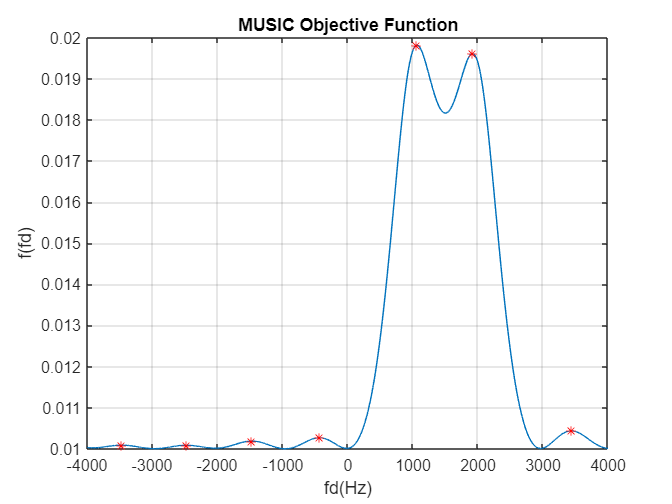


fd = (-4e3 : 1 : 4e3)'; % The Value to be found is the doppler of the targets!
s = circshift(sl , floor(2*R1/c) ).* exp(1j*2*pi*fd*t); % Signal Space with given Range  
f = 1./sum(  abs(s*Vnull).^2 ,2 ); % f(fd)

figure(6)
close all;
plot(fd , f)
xlabel('fd(Hz)')
ylabel('f(fd)')
grid on
title("MUSIC Objective Function")
[Music_peaks , Music_idx ] = findpeaks(f);
hold on
plot(fd(Music_idx),Music_peaks,"r*")